# CM4.2

function [G] = geom(p)
    G = @(s) p/(1-(1-p)*s);
end

function [x]=newton2d(g,paa,pab,pba,pbb,x0,jacobian,N,tol)
    n=0;
    x=x0;
    j=jacobian(x0,paa,pab,pba,pbb);

    % n = index of last computed x,y,jacobian = num of steps completed
    % last computed jacobian is not checked

    while n<N
        if abs(det(j))<1e-12
            error("No inverse at (%d,%d)",x(1),x(2));
        end

        %inv_j = inv(j);
        new_x = x - j\g(x);
        new_x = max(0, min(1, new_x)); 
        j = jacobian(new_x,paa,pab,pba,pbb);
        n=n+1;

        if norm(new_x-x) < tol*(1+norm(new_x))
            break;
        end

        x = new_x;
    end
end

## update label

function update_label(paa,pab,pba,pbb,x0,jacobian,N,tol,x_lbl,y_lbl)
    Gaa = geom(paa); Gab = geom(pab); Gba = geom(pba); Gbb = geom(pbb);
    g = @(x) [Gaa(x(1))*Gab(x(2))-x(1); Gba(x(1))*Gbb(x(2))-x(2)];
    [xy] = newton2d(g,paa,pab,pba,pbb,x0,jacobian,N,tol);
    
    x_lbl.Text = "x = "+num2str(xy(1)); 
    y_lbl.Text = "y = "+num2str(xy(2));
    plot_system(paa, pab, pba, pbb, xy);
end

function plot_system(paa, pab, pba, pbb, solution_xy)
    % Create a grid of points from 0 to 1 (the probability space)
    [X, Y] = meshgrid(0:0.02:1.2, 0:0.02:1.2); 
    
    % Define the Generating Functions
    G = @(p, s) p./(1-(1-p)*s);
    
    % Equation 1: Gaa(x)*Gab(y) - x = 0
    Z1 = G(paa, X) .* G(pab, Y) - X;
    
    % Equation 2: Gba(x)*Gbb(y) - y = 0
    Z2 = G(pba, X) .* G(pbb, Y) - Y;
    
    % Create the plot
    figure(2); clf;
    % Draw the line where Equation 1 is zero (Red)
    contour(X, Y, Z1, [0 0], 'r', 'LineWidth', 2, 'DisplayName', 'Eq 1 (Nullcline)');
    hold on;
    % Draw the line where Equation 2 is zero (Blue)
    contour(X, Y, Z2, [0 0], 'b', 'LineWidth', 2, 'DisplayName', 'Eq 2 (Nullcline)');
    
    % Plot the solution found by Newton's Method
    plot(solution_xy(1), solution_xy(2), 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 10, ...
        'DisplayName', 'Newton Result');
    
    % Formatting
    xlabel('x'); ylabel('y');
    title(sprintf('System Nullclines (p_{aa}=%.2f, p_{ab}=%.2f...)', paa, pab));
    grid on;
    legend('Location', 'northeast');
    axis([0 1.2 0 1.2]); % Focus on the valid probability range
end


## Driver

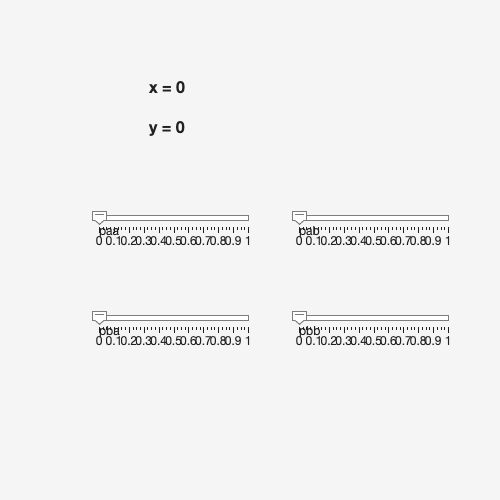

function j = jacobian(x0,paa,pab,pba,pbb)
    x = x0(1); y = x0(2);
    xaa = 1-(1-paa)*x;
    yab = 1-(1-pab)*y;
    xba = 1-(1-pba)*x;
    ybb = 1-(1-pbb)*y;
    j=zeros(2,2);
    j(1,1) = paa*pab/xaa^2/yab-1;
    j(1,2) = paa*pab/xaa/yab^2;
    j(2,1) = pba*pbb/xba^2/ybb;
    j(2,2) = pba*pbb/xba/ybb^2-1;
end

x0 = [0.5;0.5];
N = 1000;
tol = 3e-16;

fig = uifigure('Name','CM4.2','Position',[100,100,500,500]);

x_lbl = uilabel(fig,'Position',[150,400,200,30],'FontSize',16,'FontWeight','bold','Text','x = 0');
y_lbl = uilabel(fig,'Position',[150,360,200,30],'FontSize',16,'FontWeight','bold','Text','y = 0');

ticks = 0:0.1:1.0;

uilabel(fig,'Text','paa','Position',[100,260,100,20]);
paa_sld = uislider(fig,'Position',[100,280,150,3],'Limits',[0 1]);
paa_sld.MajorTicks = ticks;


uilabel(fig,'Text','pab','Position',[300,260,100,20]);
pab_sld = uislider(fig,'Position',[300,280,150,3],'Limits',[0 1]);
pab_sld.MajorTicks = ticks;

uilabel(fig,'Text','pba','Position',[100,160,100,20]);
pba_sld = uislider(fig,'Position',[100,180,150,3],'Limits',[0 1]);
pba_sld.MajorTicks = ticks;

uilabel(fig,'Text','pbb','Position',[300,160,100,20]);
pbb_sld = uislider(fig,'Position',[300,180,150,3],'Limits',[0 1]);
pbb_sld.MajorTicks = ticks;

% Shared Callback Function
cb = @(src, event) update_label(paa_sld.Value, pab_sld.Value, pba_sld.Value, pbb_sld.Value, x0, @jacobian, N, tol, x_lbl, y_lbl);

% Assign Callbacks
paa_sld.ValueChangedFcn = cb;
pab_sld.ValueChangedFcn = cb;
pba_sld.ValueChangedFcn = cb;
pbb_sld.ValueChangedFcn = cb;


function tmp(paa,pab,pba,pbb,x0,jacobian,N,tol)
    Gaa = geom(paa); Gab = geom(pab); Gba = geom(pba); Gbb = geom(pbb);
    g = @(x) [Gaa(x(1))*Gab(x(2))-x(1); Gba(x(1))*Gbb(x(2))-x(2)];
    [xy] = newton2d(g,paa,pab,pba,pbb,x0,jacobian,N,tol);
    
    fprintf("x=%f  y=%f",xy(1),xy(2));
end

tmp(0,0,1/3,2/3,x0,@jacobian,N,tol);

x=0.000000  y=0.241694